clc; clear;

% --- Inputs -----------------------------------------
Re_No = 500000;
rho = 1.225;         % Atomsphere Density (in kg/m^3)
nu = 1.7894e-05;     % Dynamic Viscosity (in N-s/m^2)
C = 0.225;             % Chord length (in  m)
B = 1.000;            % Span Length (in  m)
AR = B*B/ (B*C);     % Aspect Ratio
V_inf = (Re_No * nu)/(rho*C);   % Freestream velocity (m/s)


%------- Propeller Details ----------------------------
RPM = 2500;
n = RPM / 60;             % Rev/s
prop_Dia= 0.510;         % in m
prop_Area = pi * (prop_Dia/2)^2;  % Propeller disk area (m^2)

% --- CT-J relation (Example, empirical or assumed) ---
CT0 = 0.1;                % Max thrust coefficient
k = 0.6;                  % Decay with advance ratio
J = V_inf / (n *prop_Dia);      % Advance ratio
CT = CT0 * (1 - k * J);   % Thrust coefficient (empirical)

% --- Calculate thrust from CT ---
%prop_thrust = -CT * rho * n^2 * prop_Dia^4;
prop_thrust = 4*9.8; % in N
%Vi = sqrt(prop_thrust/(prop_Area*rho));  % Induced velocity by propeller (m/s)

% Quadratic coefficients
a = 2 * rho * prop_Area;
b = 2 * rho * prop_Area * V_inf;
c = -prop_thrust;

% Solve the quadratic using roots()
coeffs = [a, b, c];       % [a b c]
vi_roots = roots(coeffs); % Compute roots

% Choose the positive real root (physical induced velocity)
Vi = max(vi_roots(vi_roots > 0));

% Display results
fprintf('Induced velocity v_i = %.4f m/s\n', Vi);

Induced velocity v_i = 2.2561 m/s


phi = deg2rad(0);        % Propeller installation angle (rad)

% Varying freestream angle of attack (in degrees)
alpha_inf_deg = 0:1:16;   % 0 to 16 degrees
alpha_inf = deg2rad(alpha_inf_deg);   % convert to radians

% --- Compute freestream components ---
u = V_inf * cos(alpha_inf);  % x-component
v = V_inf * sin(alpha_inf);  % y-component
w = zeros(size(alpha_inf));  % z-component (freestream)

% --- Slipstream properties ---
u_slip = u + Vi * cos(phi);
v_slip = v;
w_slip = w - Vi * sin(phi);

Vs = sqrt(u_slip.^2 + v.^2 + w_slip.^2);        % Slipstream velocity magnitude

alpha_s = atan2(w_slip, u_slip);                % Slipstream angle of attack (rad)
alpha_s_deg = rad2deg(alpha_s);                 % in degrees

beta_s = atan2(v_slip, sqrt(u_slip.^2 + w_slip.^2));
beta_s_deg = rad2deg(beta_s);

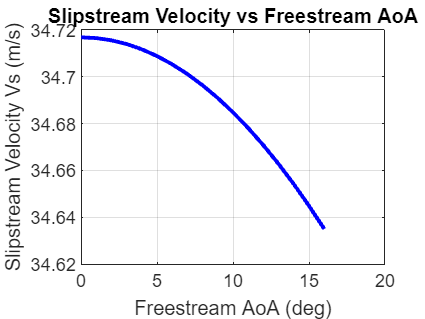


% --- Plotting ---
figure;

%subplot(3,1,1);
plot(alpha_inf_deg, Vs, 'b', 'LineWidth', 2);
xlabel('Freestream AoA (deg)');
ylabel('Slipstream Velocity Vs (m/s)');
title('Slipstream Velocity vs Freestream AoA');
grid on;


% subplot(3,1,2);
% plot(alpha_inf_deg, alpha_s_deg, 'r', 'LineWidth', 2);
% xlabel('Freestream AoA (deg)');
% ylabel('Slipstream AoA α_s (deg)');
% title('Slipstream AoA vs Freestream AoA');
% grid on;
% 
% subplot(3,1,3);
% plot(alpha_inf_deg, u_slip, 'g', 'LineWidth', 2); hold on;
% plot(alpha_inf_deg, v_slip, 'm', 'LineWidth', 2);
% xlabel('Freestream AoA (deg)');
% ylabel('Velocity Components (m/s)');
% legend('u_{slip}', 'v_{slip}');
% title('Slipstream Velocity Components');
% grid on;


% --- Tabulate sampled values ---
sample_idx = round(linspace(1, length(alpha_inf_deg), 10));  % 10 samples

% Freestream table
u_sample = u(sample_idx);
v_sample = v(sample_idx);
w_sample = w(sample_idx);

T_fs = table(alpha_inf_deg(sample_idx)', ...
             u_sample', v_sample', w_sample', ...
             'VariableNames', {'AoA_deg', 'u_fs', 'v_fs', 'w_fs'});

% Slipstream table
u_slip_sample = u_slip(sample_idx);
v_slip_sample = v_slip(sample_idx);
w_slip_sample = w_slip(sample_idx);
Vs_sample = Vs(sample_idx);
alpha_s_sample = alpha_s_deg(sample_idx);

T_slip = table(alpha_inf_deg(sample_idx)', ...
               u_slip_sample', v_slip_sample', w_slip_sample', ...
               Vs_sample', alpha_s_sample', ...
               'VariableNames', {'AoA_deg', 'u_slip', 'v_slip', 'w_slip', 'V_slip', 'alpha_s_deg'});

% --- Display tables ---
disp('--- Freestream Velocity Components ---');

--- Freestream Velocity Components ---


disp(T_fs);

    AoA_deg     u_fs      v_fs     w_fs
    _______    ______    ______    ____

       0       32.461         0     0  
       2       32.441    1.1329     0  
       4       32.382    2.2643     0  
       5       32.337    2.8291     0  
       7       32.219     3.956     0  
       9       32.061     5.078     0  
      11       31.864    6.1938     0  
      12       31.751     6.749     0  
      14       31.497     7.853     0  
      16       31.203    8.9474     0  




disp('--- Slipstream Velocity Components ---');

--- Slipstream Velocity Components ---


disp(T_slip);

    AoA_deg    u_slip    v_slip    w_slip    V_slip    alpha_s_deg
    _______    ______    ______    ______    ______    ___________

       0       34.717         0      0       34.717         0     
       2       34.697    1.1329      0       34.716         0     
       4       34.638    2.2643      0       34.712         0     
       5       34.593    2.8291      0       34.709         0     
       7       34.475     3.956      0       34.701         0     
       9       34.317     5.078      0       34.691         0     
      11        34.12    6.1938      0       34.678         0     
      12       34.007     6.749      0       34.671         0     
      14       33.753     7.853      0       34.654         0     
      16       33.459    8.9474      0       34.635       

Vi0_avg = 0.5 * (1.59 * n * prop_Dia * sqrt(CT));  % m/s

% --- Step 2: Vi_avg(x) and Rs(x) ---
Vi_avg = @(x) Vi0_avg * (1 + (x / (prop_Dia/2))) ./ sqrt(1 + (x / (prop_Dia/2)).^2);
Rs = @(x) (prop_Dia/2) .* sqrt(Vi0_avg ./ Vi_avg(x));

% --- Step 3: Slipstream area (Eq. 17) ---
x_le = -0.105;  % leading edge to propeller plane
x_te = 0.225;   % trailing edge to propeller plane
Sslip = 2 * integral(Rs, x_le, x_te);  % slipstream area (m^2)
disp(Sslip)

    0.1633



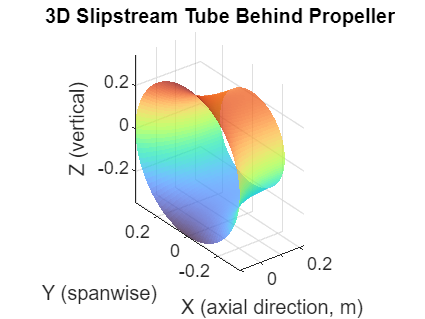

% --- Generate 3D slipstream tube surface ---
x_vals = linspace(x_le, x_te, 100);   % Axial positions from LE to TE
theta = linspace(0, 2*pi, 100);       % Angle around circumference

[X, THETA] = meshgrid(x_vals, theta);
R_vals = Rs(X(1,:));                  % Slipstream radius at each x

Y = R_vals .* cos(THETA);            % Y = R(x) * cos(θ)
Z = R_vals .* sin(THETA);            % Z = R(x) * sin(θ)

% Repeat X for matching dimensions
X = repmat(x_vals, length(theta), 1);

% --- Plot 3D Slipstream ---
figure;
surf(X, Y, Z, 'FaceAlpha', 0.7, 'EdgeColor', 'none');
xlabel('X (axial direction, m)');
ylabel('Y (spanwise)');
zlabel('Z (vertical)');
title('3D Slipstream Tube Behind Propeller');
axis equal;
grid on;
colormap turbo;